# Numpy import export for SciPy

Peter Chang

## Objective

Reading and writing actual filenames .txt, .mat, .csv and some other exchange from python runtime.

### Functions that controls path, filename and pwd

This is basic OS operation that is associated with the files window.

#### Exercise 1

Choosing the right pwd and input the .csv file so to make use of the python-matlab communication

a. the most common way of data is "ros 2 bag like" comma sepearted value

b. in matlab and python (import csv) it is easy to use the csv file to read and write the field name data

c. for ros2 message (bag) it is strongly typed fieldname 

clear all
close all

pwd                 % standard way to querying present working directory

ans = 'C:\Users\itsyu\GitHub\learning\matlab_python'

files = dir         % using dir command to make it into files structure

files = 21×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


fieldnames(files)   % finding out what are all from the directories (for each file)

ans = 6×1 cell array
    {'name'   }
    {'folder' }
    {'date'   }
    {'bytes'  }
    {'isdir'  }
    {'datenum'}


files(6)        % readout the 6th file's context

ans = struct with fields:
       name: 'c03_matlab_python_runtime_math.mlx'
     folder: 'C:\Users\itsyu\GitHub\learning\matlab_python'
       date: '19-Aug-2026 11:35:21'
      bytes: 9569
      isdir: 0
    datenum: 7.4021e+05


files(8).name   % specifcally get the filename of the 8th file

ans = 'e05_matlab_export.mat'


isfile("robot_log.txt")

ans = logical
   1


isfile("robot_log.csv")

ans = logical
   1



% read in robot_log.txt, with python it is with open("robot_log.csv") as filename: 
filename = fullfile(pwd,"robot_log.csv");   % then reader = csv.DictReader(filename) in python
data = readmatrix(filename)         % can manually import but this is more auto

data =          0   -0.6691    0.5377
    0.0100   -0.4003    1.8339
    0.0200   -0.6718   -2.2588
    0.0300    0.5756    0.8622
    0.0400   -0.7781    0.3188
    0.0500   -1.0636   -1.3077
    0.0600    0.5530   -0.4336
    0.0700   -0.4234    0.3426
    0.0800    0.3616    3.5784
    0.0900   -0.3519    2.7694
    0.1000    0.2695   -1.3499
    0.1100   -2.5644    3.0349
    0.1200    0.4659    0.7254
    0.1300    1.8536   -0.0631
    0.1400    1.0393    0.7147



robot_log.time = data(:,1);         % using data file that read the filename, knowing the defined data fields
robot_log.position = data(:,2);
robot_log.velocity = data(:,3);

The above uses csv files that is general to all computer systems, and this makes the natural transition towards reading structured data files.

We now log simple data plots that is famous on MATLAB

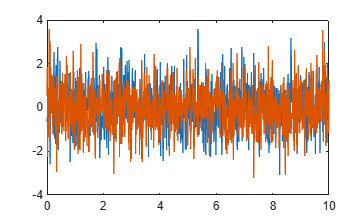

figure(01)
plot(robot_log.time, robot_log.position)
hold on
plot(robot_log.time, robot_log.velocity)

Recall that we've saved some numpy array into the .mat file that is for matlab use

"e05_python_export.mat"

- we can directly click on it to import them into matlab workspace

- we can import and open the file with a filename variable

isfile("e05_python_export.mat")

ans = logical
   1



data = load("e05_python_export.mat")    % recall that data was previously used as a matrix

data = struct with fields:
             A: [2×3 double]
    robot_data: [1×1 struct]


data_filedname = fieldnames(data)   % this data is only used for matlab local 

data_filedname = 2×1 cell array
    {'A'         }
    {'robot_data'}


Assuming we've got a nice ROS2 message type definition, as in .msg

We'd like to extract the data from the read-in, so we'd now take the two data filednames individually

a_variabl = data.A                      % extract for local use

a_variabl =      1     2     3
     4     5     6


robot_data = data.robot_data    % local use

robot_data = struct with fields:
    velocity: 1.2000
    position: [-1.5000 3.5000]
      status: 0


robot_data.position

ans =    -1.5000    3.5000


robot_data.status

ans = logical
   0


robot_data.velocity

ans = 1.2000

It is natrual for use to modify and save another version of the matrix and other modeling or data-log for robotics, thus we need to save and provide another file for matlab to export this into a file

"e05_matlab_export.mat" for python to read-in.

% assume a standard m-k-s system for a two by two matrix to develope A, B,
% C, D matrix
m = 1;
k = 1;
c = 0.5;

A = [0 1;-k/m -c/m];    % change a matrix
B = [0;1/m];
C = eye(2);
D = 0;

t = 0:0.01:10;
vel = randn(size(t));
pos = randn(size(t));

robot_data.position = pos;
robot_data.velocity = vel;
robot_data.t = t;
robot_data.status

ans = logical
   0



save("e05_matlab_export.mat", "A", "robot_data")

Let us change the robot_log.csv file into our local matlab version

% filename = fullfile(pwd,"robot_log.csv");
filename

filename = "C:\Users\itsyu\GitHub\learning\matlab_python\robot_log.csv"

data    % check original data

data = struct with fields:
             A: [2×3 double]
    robot_data: [1×1 struct]


data = table(t',pos',vel',...
    'VariableNames',{'time','position','velocity'});

writetable(data,filename)

### Exercise 2

Using MATLAB to compare with numpy

A

A =          0    1.0000
   -1.0000   -0.5000


B

B =      0
     1


C

C =      1     0
     0     1


D

D = 0


C = zeros(2,2)

C =      0     0
     0     0


C = ones(2,2)

C =      1     1
     1     1


C = eye(2)

C =      1     0
     0     1



A.* C

ans =          0         0
         0   -0.5000


A * C

ans =          0    1.0000
   -1.0000   -0.5000


Recall that we've used the 2nd order Newton's law system (m-k-s) to demonstrate simulation


$$\dot{x}  = \mathbb{A}x+\mathbb{B}u \\
y = \mathbb{C}x +\mathbb{D} u
$$


% it is standard to use ode45 as a function to solve with time step and
% this requires a initial condition and pre-designed input scenario

% initial condition with mass placed at 3.0 m, with negative 0.2 m/s
x0 = [3.0 -0.2];
% physically there is a elongated spring, and a hand that pushes inward,
% but no force acting, called zero input scenario

This is usual for numerical simulation, we start with a for loop and pre-assign a time-line like in simulink

disp(["simulation time duration start from:", t(1)," ends at", t(end)])

    "simulation time duration start from:"    "0"    " ends at"    "10"



disp(["there will be time steps of:",length(t)])

    "there will be time steps of:"    "1001"




% let us pre-assign x solution
x = zeros(2,length(t));
y = zeros(2,length(t));

u = zeros(1,length(t)); % zero input throughout similation time

x(:,1) = x0;  % put in initial condition
y(:,1) = C*x(:,1) + D*u(1)

y =     3.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.2000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

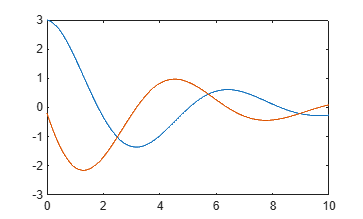


for i = 2:length(t)
    dt = t(i)-t(i-1);

    x_dot = A * x(:,i-1) + B * u(i-1);

    x(:,i) = x(:,i-1) + x_dot * dt;

    y(:,i) = C * x(:,i) + D * u(i);
end

figure(02)
plot(t,x(1,:))
hold on
plot(t,x(2,:))

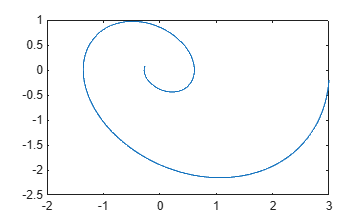


figure(03)
plot(x(1,:),x(2,:)) % phase diagram

### Exercise 3

Using MATLAB to calculate ode45 solver, with comparison to g07_python_numpy_matplot

The earlier for loop was self explanatory in integrating our dynamic equation and iterating our output equation

It is more common to use an ODE solver to perform such a numerical simulation

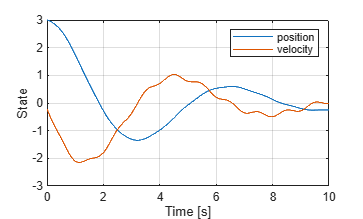

%% Exercise: Solve the state equation using ode45

% State equation
% x_dot = A*x

% note: we need to use a constant input u0=0 or u0=1 to constantly drive
% our state equation, or if forced input such as u(t) = A*sin(2*pi*t), then
% the state equation need to be fixed as that

f = 1; % one hertz frequency
state_eq = @(t,x) A*x + B*(0.5*sin(2*pi*f*t));    % @(t,x) Ax+Bu must return a column vector

% Solve
[t_ode, x_ode] = ode45(state_eq, t, x0);

% Plot
figure(04)
plot(t_ode, x_ode(:,1), 'DisplayName', 'position')
hold on
plot(t_ode, x_ode(:,2), 'DisplayName', 'velocity')

xlabel('Time [s]')
ylabel('State')
legend
grid on